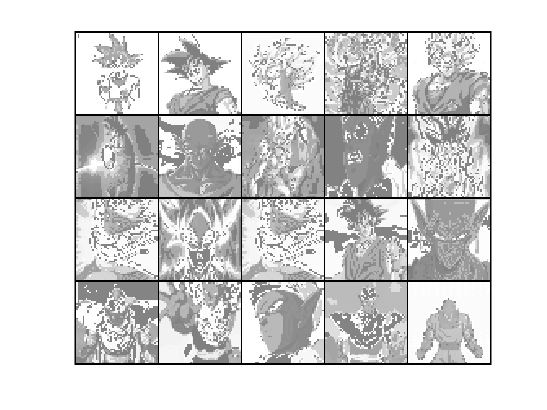

Iterations = 2000;
X = [goku_matrix; piccolo_matrix];
m = size(X, 1);

% Randomly select 20 data points to display
sel = randperm(size(X, 1));
sel = sel(1:20);
displayData(X(sel, :));


y = [ones(40,1); 2*ones(40,1)];



Theta1 = zeros(25,2501);
Theta2 = zeros(2,26);



input_layer_size  = 2500;  % 20x20 Input Images of Digits
hidden_layer_size = 25;   % 25 hidden units
num_labels = 2;          % 10 labels, from 1 to 10 (note that we have mapped "0" to label 10)

% Unroll parameters 
nn_params = [Theta1(:) ; Theta2(:)];

% Weight regularization parameter (we set this to 0 here).
lambda = 0;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

fprintf('Cost at parameters (loaded from ex4weights): %f', J);

Cost at parameters (loaded from ex4weights): 1.386294




% Weight regularization parameter (we set this to 1 here).
lambda = 1;

J = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at parameters (loaded from ex4weights): %f', J);

Cost at parameters (loaded from ex4weights): 1.386294




% Call your sigmoidGradient function
sigmoidGradient(0)

ans = 0.2500




initial_Theta1 = randInitializeWeights(input_layer_size, hidden_layer_size);
initial_Theta2 = randInitializeWeights(hidden_layer_size, num_labels);

% Unroll parameters
initial_nn_params = [initial_Theta1(:) ; initial_Theta2(:)];


checkNNGradients;

   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
    0.0000    0.0000
   -0.0000   -0.0000
   -0.0002   -0.0002
    0.0002    0.0002
   -0.0003   -0.0003
    0.0003    0.0003
   -0.0004   -0.0004
   -0.0001   -0.0001
    0.0001    0.0001
   -0.0001   -0.0001
    0.0002    0.0002
   -0.0002   -0.0002
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1641    0.1641
    0.0576    0.0576
    0.0505    0.0505
    0.1646    0.1646
    0.0578    0.0578
    0.0508    0.0508
    0.1583    0.1583
    0.0559    0.0559
    0.0492    0.0492
    0.1511    0.1511
    0.0537    0.0537
    0.0471    0.0471
    0.1496    0.1496
    0.0532    0.0532
    0.0466    0.0466

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be



%  Check gradients by running checkNNGradients
lambda = 3;
checkNNGradients(lambda);

   -0.0093   -0.0093
    0.0089    0.0089
   -0.0084   -0.0084
    0.0076    0.0076
   -0.0067   -0.0067
   -0.0168   -0.0168
    0.0394    0.0394
    0.0593    0.0593
    0.0248    0.0248
   -0.0327   -0.0327
   -0.0602   -0.0602
   -0.0320   -0.0320
    0.0249    0.0249
    0.0598    0.0598
    0.0386    0.0386
   -0.0174   -0.0174
   -0.0576   -0.0576
   -0.0452   -0.0452
    0.0091    0.0091
    0.0546    0.0546
    0.3145    0.3145
    0.1111    0.1111
    0.0974    0.0974
    0.1187    0.1187
    0.0000    0.0000
    0.0337    0.0337
    0.2040    0.2040
    0.1171    0.1171
    0.0755    0.0755
    0.1257    0.1257
   -0.0041   -0.0041
    0.0170    0.0170
    0.1763    0.1763
    0.1131    0.1131
    0.0862    0.0862
    0.1323    0.1323
   -0.0045   -0.0045
    0.0015    0.0015

The above two columns you get should be very similar.
(Left-Your Numerical Gradient, Right-Analytical Gradient)

If your backpropagation implementation is correct, then 
the relative difference will be



% Also output the costFunction debugging value 
% This value should be about 0.576051
debug_J  = nnCostFunction(nn_params, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);
fprintf('Cost at (fixed) debugging parameters (w/ lambda = 3): %f', debug_J);

Cost at (fixed) debugging parameters (w/ lambda = 3): 1.386294




options = optimset('MaxIter', Iterations);    %Iterations at the top of the code
lambda = 1;

% Create "short hand" for the cost function to be minimized
costFunction = @(p) nnCostFunction(p, input_layer_size, hidden_layer_size, num_labels, X, y, lambda);

% Now, costFunction is a function that takes in only one argument (the
% neural network parameters)
[nn_params, ~] = fmincg(costFunction, initial_nn_params, options);

Iteration     1 | Cost: 3.262074e+00
Iteration     2 | Cost: 3.237206e+00
Iteration     3 | Cost: 3.168693e+00
Iteration     4 | Cost: 3.072956e+00
Iteration     5 | Cost: 3.071438e+00
Iteration     6 | Cost: 3.065748e+00
Iteration     7 | Cost: 2.940614e+00
Iteration     8 | Cost: 2.940248e+00
Iteration     9 | Cost: 2.893108e+00
Iteration    10 | Cost: 2.879006e+00
Iteration    11 | Cost: 2.860404e+00
Iteration    12 | Cost: 2.787635e+00
Iteration    13 | Cost: 2.296153e+00
Iteration    14 | Cost: 1.779726e+00
Iteration    15 | Cost: 1.760189e+00
Iteration    16 | Cost: 1.755217e+00
Iteration    17 | Cost: 1.754888e+00
Iteration    18 | Cost: 1.748453e+00
Iteration    19 | Cost: 1.733578e+00
Iteration    20 | Cost: 1.730213e+00
Iteration    21 | Cost: 1.729655e+00
Iteration    22 | Cost: 1.726675e+00
Iteration    23 | Cost: 1.724965e+00
Iteration    24 | Cost: 1.715918e+00
Iteration    25 | Cost: 1.705196e+00
Iteration    26 | Cost: 1.705040e+00
Iteration    27 | Cost: 1.702023e+00
I




% Obtain Theta1 and Theta2 back from nn_params
Theta1 = reshape(nn_params(1:hidden_layer_size * (input_layer_size + 1)), hidden_layer_size, (input_layer_size + 1));
Theta2 = reshape(nn_params((1 + (hidden_layer_size * (input_layer_size + 1))):end), num_labels, (hidden_layer_size + 1));
 
pred = predict(Theta1, Theta2, X);
fprintf('\nTraining Set Accuracy: %f\n', mean(double(pred == y)) * 100);


Training Set Accuracy: 100.000000




pred = predict(Theta1, Theta2, X)

pred =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


pred = predict(Theta1, Theta2, test_goku_matrix)

pred =      2
     2
     1
     1
     1
     1
     1
     2
     1



c = 9;
for i = 1:c
if pred(i) == 1
    disp("Goku")
else
    disp("Piccolo")
end
end

Piccolo
Piccolo


Goku
Goku
Goku
Goku
Goku


Piccolo


Goku
